# Transfer Learning - Image Classification *(100 points)*

## 1. Pretrained network

###     1.1. Import SqueezeNet

net = squeezenet %Import SqueezeNet

net =   DAGNetwork - 속성 있음:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


###     1.2. What is the input image size of SqueezeNet?

      Enter your code to ouput the input image size of SqueezeNet.

layers = net.Layers

layers =   다음 계층을 포함한 68×1 Layer 배열:

     1   'data'                              영상 입력              227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'                             2차원 컨벌루션          64개 3×3×3 컨벌루션(스트라이드: [2  2], 채우기: [0  0  0  0])
     3   'relu_conv1'                        ReLU                  ReLU
     4   'pool1'                             2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     5   'fire2-squeeze1x1'                  2차원 컨벌루션          16개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     6   'fire2-relu_squeeze1x1'             ReLU                  ReLU
     7   'fire2-expand1x1'                   2차원 컨벌루션          64개 1×1×16 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     8   'fire2-relu_expand1x1'              ReLU                  ReLU
     9   'fire2-expand3x3'                   2차원 컨벌루션          64개 3×3×16 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    10   'fir

layers_input = layers(1)

layers_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]


layers_output = layers(end)

layers_output =   ClassificationOutputLayer - 속성 있음:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'


classes = layers_output.Classes

classes = 1000×1 categorical 배열
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


sz = layers_input.InputSize % input image size of SqueezeNet.

sz =    227   227     3


## 2. Importing dataset

###     2.1. Create an image datastore

      Create an image datastore which references the folder of the dataset.

imageDS = imageDatastore("raw-img_shrinked/", "IncludeSubfolders",true,...
    "LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1997 more
                              }
                     Folders: {
                              ' .../Documents/MATLAB/인공지능/Assignment2/raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
         

###     2.2 What ouput classes does the dataset contain?

      Enter your code to output the classes of the dataset.

categories(imageDS.Labels)

ans = 10×1 cell 배열
    {'butterfly'}
    {'cat'      }
    {'chicken'  }
    {'cow'      }
    {'dog'      }
    {'elephant' }
    {'horse'    }
    {'sheep'    }
    {'spider'   }
    {'squirrel' }


*           View a sample image of each class*

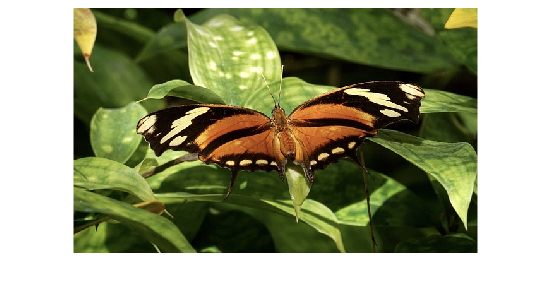

    %-------------- DO NOT modify this code--------------
    selectedClass="butterfly";
    classIdx = contains(imageDS.Files,selectedClass);
    countClass = sum(classIdx);
    randNum = randi([1,countClass],1);
    classRowNum = find(classIdx);
    classRandIm = readimage(imageDS, classRowNum(1)+randNum-1);
    imshow(classRandIm)

    %----------------------------------------------------

## 3. Preparing Data

###     3.1. Split dataset

      Split the dataset into train(0.8) and test data(0.2). 

- **DO NOT include validation data.**

- **For an optional argument, input "**`randomized`**" option.**

[TrainImages, TestImages] = splitEachLabel(imageDS, 0.8, "randomized")

TrainImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1597 more
                              }
                     Folders: {
                              ' .../Documents/MATLAB/인공지능/Assignment2/raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
     

TestImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../e030b2092ce90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' .../e030b2092de90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' ...31b00c2ef3093ed1584d05fb1d4e9fe777ead218ac104497f5c97faee9bdba_640.jpg'
                               ... and 397 more
                              }
                     Folders: {
                              ' .../Documents/MATLAB/인공지능/Assignment2/raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 397 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
       

%For an optional argument, input "randomized" option.??

###     3.2. Augment data

      Resize the dataset for transfer learning. 

- **For an optional input argument, input "**`gray2rgb`**" for "**`ColorPreprocessing`**" option.**

TrainData = augmentedImageDatastore([227,227,3],TrainImages,"ColorPreprocessing","gray2rgb")

TrainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1600
                       Files: {1600×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


TestData = augmentedImageDatastore([227,227,3],TestImages,"ColorPreprocessing","gray2rgb")

TestData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 400
                       Files: {400×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 4. Modifying Network

Modify appropriate layers of SqueezeNet so that the network works for your dataset. Follow the steps below.

- Open **Deep Network Designer App** to modify the network. 

- Replace the last 2-D convolutional layer(64th layer) of the network. In order to replace the layer, drag a new `convolution2dLayer` onto the canvas. To match the original convolutional layer, set `FilterSize` to `1,1`. Edit `NumFilters` to be the number of classes in the new data, in the case of this question, 10. Delete the original 2-D convolutional layer and connect your new layer instead. 

-  Replace the final classification layer(68th layer). In order to replace the layer, drag a new `classificationLayer` onto the canvas. Delete the original output layer and connect your new layer in its place.

- If you complete the modification of the network, in the App, use **'Export network to workspace'** to export the network to your workspace. Your new network will be saved as `'lgraph_1'` in the workspace.

- **Be sure to include your network(**`'lgraph_1'`**) into the zip file, when you submit your file.**

## 5. Training Network

Create appropriate training options to obtain good prediction accuracy for the test data.

###     5.1. Create training options

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- Max Epochs: 10

- **DO NOT DISPLAY** training progress

opts = trainingOptions("sgdm","InitialLearnRate",0.01,...
    "MaxEpochs",10,"LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",3,"LearnRateDropFactor",0.3, "MiniBatchSize",32,"GradientThreshold",1,...
    "Shuffle","every-epoch")

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.3000
             LearnRateDropPeriod: 3
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 10
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 1
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                     

###     5.2. Train Network

      Train network. If you see a sytax error when starting the training, and be required to add an optional argument in 3.2.

newnet = trainNetwork(TrainData,lgraph_1,opts)

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　검증　정확도　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：１５　｜　　　　　　１２．５０％　｜　　　１３．７５％　｜　　　　　４．７３６７　｜　　４．１１８６　｜　　　０．０１００　｜
｜　　　　　　　１　｜　　　　　　　２　｜　　　　　００：００：２３　｜　　　　　　１２．５０％　｜　　　１６．５０％　｜　　　　　４．０２０３　｜　　３．２１７６　｜　　　０．０１００　｜
｜　　　　　　　１　｜　　　　　　　３　｜　　　　　００：００：３１　｜　　　　　　　９．３８％　｜　　　１７．７５％　｜　　　　　３．５７６０　｜　　２．６１８２　｜　　　０．０１００　｜
｜　　　　　　　１　｜　　　　　　　４　｜　　　　　００：００：３７　｜　　　　　　１８．７５％　｜　　　１８．００％　｜　　　　　２．４９２６　｜　　２．３２７９　｜　　　０．０１００　｜
｜　　　　　　　１　｜　　　　　　　５　｜　　　　　００：００：４５　｜　　　　　　２５．００％　｜　　　２４．２５％　｜　　　　　２．３３８９　｜　　２．２１９９　｜　　　０．０１００　｜
｜　　　　　　　１　｜　　　　　　　６　｜　　　　　００：００：５１　｜　　　　　　１５．６２％　｜　　　２７．２５％　｜　　　　　２．１５４４　｜　　２．１６３９　｜　　　０．０１００　｜

newnet =   DAGNetwork - 속성 있음:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     InputNames: {'data'}
    OutputNames: {'newclassoutput'}


## 6. Evaluating network

Evaluate the network by classifying the test data, calculating the classification accuracy and displaying a confusion chart.

###     6.1. Predict the class of the test data

testPred = classify(newnet, TestData)

testPred = 400×1 categorical 배열
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     spider 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 


###     6.2. Calculate the prediction accuracy (100)

- Accuracy x 100 = your score obtained from assignment2

testGT = TestImages.Labels

testGT = 400×1 categorical 배열
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 


Acc = nnz(testGT == testPred)/numel(testGT)

Acc = 0.8525

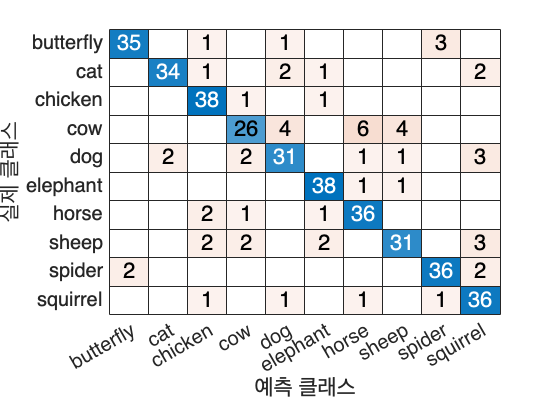

confusionchart(testGT, testPred)